y'' + y = sin(x), 

y(0) = 0, y'(0) = 1

% Define the differential equation
f = @(x,y) [y(2); -y(1) + sin(x)];

% Define the initial conditions
y0 = [0; 1];

% Define the exact solution
y_exact = @(x) 0.5.*(3.*sin(x) - x.*cos(x));

% Define the time interval and step size
t0 = 0;
tf = 10000;
h = 0.1;
tspan = t0:h:tf;

% Implement the Adams-Bashforth method
tic;
[t_ab, y_ab] = adams_bashforth(f, y0, tspan, h);
time_AB = toc * 1000;

y_ab(:,1)

ans = 1.0e+03 *

         0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009



% Implement the Adams-Moulton method
tic;
[t_am, y_am] = adams_moulton(f, y0, tspan, h);
time_AM = toc * 1000;

y_am(:,1)

ans = 1.0e+03 *

         0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0005
    0.0006
    0.0007
    0.0008
    0.0009



% Calculate the exact solution
y_exact_sol = y_exact(tspan);

% Calculate the errors
error_ab = abs(y_ab(:,1).' - y_exact_sol);
error_am = abs(y_am(:,1).' - y_exact_sol);

% Calculate the time taken by each method
%time_ab = sum(t_ab);
%time_am = sum(t_am);

% Error per
per_error_arr_ab = abs(error_ab ./ y_exact_sol * 100)

per_error_arr_ab = 1.0e+05 *

       NaN    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


per_error_arr_am = abs(error_am ./ y_exact_sol * 100)

per_error_arr_am = 1.0e+05 *

       NaN    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% Mean Error Per
mean_error_ab = mean(per_error_arr_ab(2:end))

mean_error_ab = 61.9058

mean_error_am = mean(per_error_arr_am(2:end))

mean_error_am = 42.0656

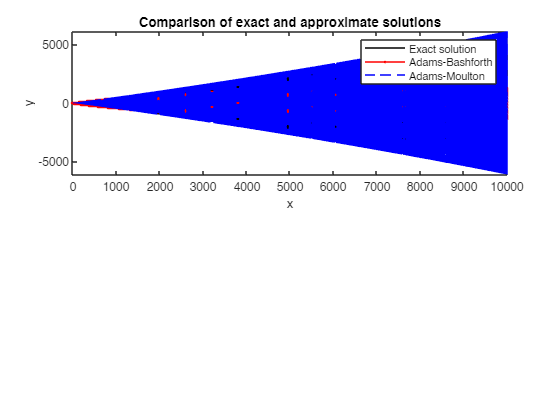


% Plot the results
figure
subplot(2,1,1)
plot(tspan, y_exact_sol, 'k-', t_ab, y_ab(:,1), 'r.-', t_am, y_am(:,1), 'b--')
legend('Exact solution', 'Adams-Bashforth', 'Adams-Moulton')
xlabel('x')
ylabel('y')
title('Comparison of exact and approximate solutions')


% Print the time taken for each method
fprintf('Time taken for Adams-Bashforth method: %f milliseconds\n', time_AB);

Time taken for Adams-Bashforth method: 164.172500 milliseconds


fprintf('Time taken for Adams-Moulton method: %f milliseconds\n', time_AM);

Time taken for Adams-Moulton method: 292.553300 milliseconds


function [t, y] = adams_bashforth(f, y0, tspan, h)
% Solve an ODE using the Adams-Bashforth method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Bashforth method to compute the remaining values of y
for i = 3:length(t)-1
    y(i+1,:) = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
end
end


function [t, y] = adams_moulton(f, y0, tspan, h)
% Solve an ODE using the Adams-Moulton method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Moulton method to compute the remaining values of y
for i = 3:length(t)-1
    % Adams-Bashforth Order 3 (yn+3)
    y_predictor = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
    % Corrector using Adams-Moulton method of order 3 (yn+2)
    y_corrector = y(i,:) + (h/12)*(5*f(t(i+1), y_predictor) + 8*f(t(i), y(i,:)) - f(t(i-1), y(i-1,:)))';
    y(i+1,:) = y_corrector;
end

end